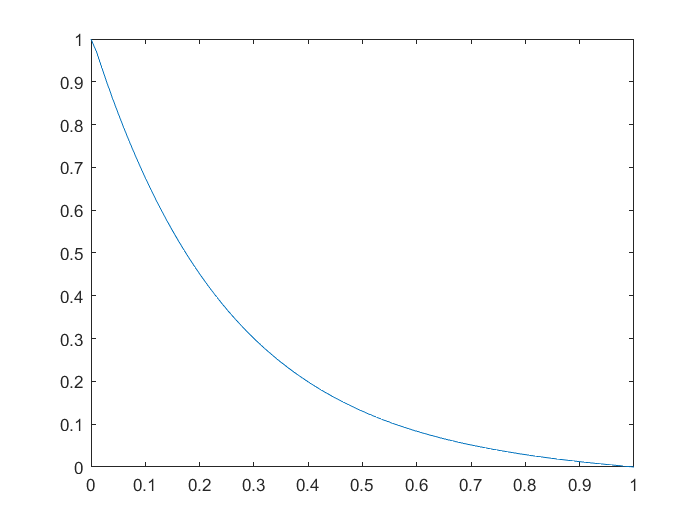

x0 = 0;
xf = 1;
ya = 1;
yb = 0;
n = 100;
h = (xf-x0)/(n-1);
d = ones(n-2)*(2+8*h^2);
u = ones(n-2)*(-1)*(1+h);
l = ones(n-2)*(-1)*(1-h);
b = zeros(n-2,1);
b(1) = ya;
b(n) = yb;
x = x0:h:xf;
yin = tridiagonal_vectores(u,l,d,b);
y = [ya;yin;yb];
plot(x,y)